clear;
clc;

% Lapso temporal
t = linspace(0, 3e4, 1e6);

% Constantes (SSO)
mu = 3.986004418e14;
J2 = 1.082635854e-3;
R = 6378.137e3;
a = 7211.54e3;
e = 0.01;
n = sqrt(mu / a^3);
INC     = deg2rad(98.7);
omega   = deg2rad(30);
theta_0 = deg2rad(45);

% Condiciones iniciales
x0  = 0;
y0  = 0;
z0  = 0;
dx0 = 0;
dy0 = 0;
dz0 = 0;

% Identidades trigonométricas
nt = n.*t;
cnt = cos(nt);
snt = sin(nt);
c2nt = cos(2.*nt);
s2nt = sin(2.*nt);
c3nt = cos(3.*nt);
s3nt = sin(3.*nt);

si = sin(INC);
ci = cos(INC);
sw = sin(omega);
cw = cos(omega);
s2w = sin(2*omega);
c2w = cos(2*omega);
s3w = sin(3*omega);
c3w = cos(3*omega);

delta = 2*(theta_0 - e*(1 + sqrt(1 - e^2))*sin(theta_0));
sd2 = sin(delta/2);
cd2 = cos(delta/2);
theta_c = omega + theta_0 - 2*e*sd2;

% Constantes de Kéchichian
f0    =   - e*cos(theta_c - delta/2);
f(1)  =     - sin(theta_c);
f(2)  =       cos(theta_c);
f(3)  =   - e*sin(theta_c + delta/2);
f(4)  =     e*cos(theta_c + delta/2);
f(5)  =   2*e*sin(2*theta_c - delta/2);
f(6)  = - 2*e*cos(2*theta_c - delta/2);
f(7)  =     - sin(2*theta_c);
fp(7) = - 2*e*sin(2*theta_c + delta/2);
f(8)  =       cos(2*theta_c);
fp(8) =   2*e*cos(2*theta_c + delta/2);

g0    =   - e*sin(theta_c - delta/2);
g(1)  =       cos(theta_c);
g(2)  =       sin(theta_c);
g(3)  =     e*cos(theta_c + delta/2);
g(4)  =     e*sin(theta_c + delta/2);
g(5)  = - 2*e*cos(2*theta_c - delta/2);
g(6)  = - 2*e*sin(2*theta_c - delta/2);
g(7)  =       cos(2*theta_c);
gp(7) =   2*e*cos(2*theta_c + delta/2);
g(8)  =       sin(2*theta_c);
gp(8) =   2*e*sin(2*theta_c + delta/2);

ac(1)  = - 3*n^2*J2*R^2*si^2/(a*(1 - e^2)^4);
ap(1)  = - 3*n^2*J2*R^2/(2*a*(1 - e^2)^4);
app(1) = - 3*n^2*J2*R^2*si*ci/(1 - e^2)^4;
ac(2)  =   cw*f0 +   sw*g0;
ac(3)  = cw*f(1) + sw*g(1);
ac(4)  = cw*f(2) + sw*g(2);
ac(5)  = cw*f(3) + sw*g(3);
ac(6)  = cw*f(4) + sw*g(4);

b0    = ac(1)*e*(ac(3)*g(5) + ac(4)*g(6) + ac(5)*g(7) + ac(6)*g(8));
b(1)  = ac(1)*( g(5)/2 + 2*e*ac(2)*g(5) -   e*ac(6)*g(5) +   e*ac(5)*g(6) +  e*ac(4)*g(7)  -   e*ac(3)* g(8) + e*ac(6)*gp(7) - e*ac(5)*gp(8));
bp(1) = ac(1)*( g(6)/2 +   e*ac(5)*g(5) + 2*e*ac(2)*g(6) +   e*ac(6)*g(6) +  e*ac(3)*g(7)  +   e*ac(4)* g(8) + e*ac(5)*gp(7) + e*ac(6)*gp(8));
b(2)  = ac(1)*( g(7)/2 +   e*ac(4)*g(5) +   e*ac(3)*g(6) + 2*e*ac(2)*g(7) + e*ac(4)*gp(7) -   e*ac(3)*gp(8));
bp(2) = ac(1)*( g(8)/2 -   e*ac(3)*g(5) +   e*ac(4)*g(6) + 2*e*ac(2)*g(8) + e*ac(3)*gp(7) +   e*ac(4)*gp(8));
b(3)  = ac(1)*(gp(7)/2 +   e*ac(6)*g(5) +   e*ac(5)*g(6) +   e*ac(4)*g(7) +  e*ac(3)*g(8) + 2*e*ac(2)*gp(7));
bp(3) = ac(1)*(gp(8)/2 -   e*ac(5)*g(5) +   e*ac(6)*g(6) -   e*ac(3)*g(7) +  e*ac(4)*g(8) + 2*e*ac(2)*gp(8));
b(4)  = ac(1)*e*( ac(6)*g(7) + ac(5)*g(8) + ac(4)*gp(7) + ac(3)*gp(8));
bp(4) = ac(1)*e*(-ac(5)*g(7) + ac(6)*g(8) - ac(3)*gp(7) + ac(4)*gp(8));
b(5)  = ac(1)*e*(ac(6)*gp(7) + ac(5)*g(8));
bp(5) = ac(1)*e*(ac(6)*gp(8) - ac(5)*g(7));

c0    = ap(1)*(1 - 3/2*si^2  + ac(2)*e*(4 - 6*si^2) + 6*e*si^2*( ac(3)/2*f(5) + ac(4)/2*f(6) + ac(5)/2*f(7) + ac(6)/2*f(8)));
c(1)  = ap(1)*(3/2*si^2*f(5) + ac(3)*e*(4 - 6*si^2) + 6*e*si^2*( ac(2)  *f(5) - ac(6)/2*f(5) + ac(5)/2*f(6) + ac(4)/2*f(7) - ac(3)/2*f(8) + ac(6)/2*fp(7) - ac(5)/2*fp(8)));
cp(1) = ap(1)*(3/2*si^2*f(6) + ac(4)*e*(4 - 6*si^2) + 6*e*si^2*( ac(5)/2*f(5) + ac(2)  *f(6) + ac(6)/2*f(6) + ac(3)/2*f(7) + ac(4)/2*f(8) + ac(5)/2*fp(7) + ac(6)/2*fp(8)));
c(2)  = ap(1)*(3/2*si^2*f(7) + ac(5)*e*(4 - 6*si^2) + 6*e*si^2*( ac(4)/2*f(5) + ac(3)/2*f(6) + ac(2)  *f(7) + ac(4)/2*fp(7) - ac(3)/2*fp(8)));
cp(2) = ap(1)*(3/2*si^2*f(8) + ac(6)*e*(4 - 6*si^2) + 6*e*si^2*(-ac(3)/2*f(5) + ac(4)/2*f(6) + ac(2)  *f(8) + ac(3)/2*fp(7) + ac(4)/2*fp(8)));
c(3)  = 3/2*si^2*ap(1)*fp(7) + ap(1)*6*e*si^2*(  ac(6)/2*f(5) + ac(5)/2*f(6) + ac(4)/2*f(7) + ac(3)/2*f(8) + ac(2)*fp(7));
cp(3) = 3/2*si^2*ap(1)*fp(8) + ap(1)*6*e*si^2*(- ac(5)/2*f(5) + ac(6)/2*f(6) - ac(3)/2*f(7) + ac(4)/2*f(8) + ac(2)*fp(8));
c(4)  = ap(1)*6*e*si^2*(  ac(6)/2*f(7) + ac(5)/2*f(8) + ac(4)/2*fp(7) + ac(3)/2*fp(8));
cp(4) = ap(1)*6*e*si^2*(- ac(5)/2*f(7) + ac(6)/2*f(8) - ac(3)/2*fp(7) + ac(4)/2*fp(8));
c(5)  = 3*ap(1)*e*si^2*(ac(6)*fp(7) + ac(5)*fp(8));
cp(5) = 3*ap(1)*e*si^2*(ac(6)*fp(8) - ac(5)*fp(7));

d0    = app(1)*(g0   + 4*e*ac(2)*g0   + 2*e*ac(3)*g(1) + 2*e*ac(4)*g(2) + 2*e*ac(5)*g(3) + 2*e*ac(6)*g(4));
d(1)  = app(1)*(g(1) + 4*e*ac(2)*g(1) + 4*e*ac(3)*g0   - 2*e*ac(3)*g(4) + 2*e*ac(4)*g(3) + 2*e*ac(5)*g(2) - 2*e*ac(6)*g(1));
dp(1) = app(1)*(g(2) + 4*e*ac(2)*g(2) + 2*e*ac(3)*g(3) + 2*e*ac(4)*g(4) + 4*e*ac(4)*g0   + 2*e*ac(5)*g(1) + 2*e*ac(6)*g(2));
d(2)  = app(1)*(g(3) + 4*e*ac(2)*g(3) + 2*e*ac(3)*g(2) + 2*e*ac(4)*g(1) + 4*e*ac(5)*g0);
dp(2) = app(1)*(g(4) + 4*e*ac(2)*g(4) - 2*e*ac(3)*g(1) + 2*e*ac(4)*g(2) + 4*e*ac(6)*g0);
d(3)  = app(1)*2*e*(  ac(3)*g(4) + ac(4)*g(3) + ac(5)*g(2) + ac(6)*g(1));
dp(3) = app(1)*2*e*(- ac(3)*g(3) + ac(4)*g(4) - ac(5)*g(1) + ac(6)*g(2));
d(4)  = app(1)*2*e*(  ac(5)*g(4) + ac(6)*g(3));
dp(4) = app(1)*2*e*(- ac(5)*g(3) + ac(6)*g(4));

ep1 = dz0/n;
ep2 = z0;
kp1 = dx0/n;
kp2 = x0;
K   = dy0 + 2*n*x0 + sum(arrayfun(@(j) b(j)/(j*n) , 1:5));
Kp  = y0 - 2*kp1 + 4*b0/n^2 ...
      - sum(arrayfun(@(j) 2/(j*n^2)*(2*bp(j)/j + c(j)) , 2:5)) ...
      + sum(arrayfun(@(j) bp(j)/(j^2*n^2) , 1:5)) ...
      - 2/n^2*(2*bp(1) + c(1));

% Solución analítica
xJ2B = ((256.*a.*n - 192.*a.*n.*cos(n.*t) - 1024.*a.*e.^2.*n + 1536.*a.*e.^4.*n - 1024.*a.*e.^6.*n + 256.*a.*e.^8.*n + 768.*a.*e.^2.*n.*cos(n.*t) - 1152.*a.*e.^4.*n.*cos(n.*t) + 768.*a.*e.^6.*n.*cos(n.*t) - 192.*a.*e.^8.*n.*cos(n.*t))./(a.*n.*(- 1 + e.^2).^4.*64)).*x0 + ((64.*sin(n.*t).*a - 256.*sin(n.*t).*a.*e.^2 + 384.*sin(n.*t).*a.*e.^4 - 256.*sin(n.*t).*a.*e.^6 + 64.*sin(n.*t).*a.*e.^8)./(a.*n.*(- 1 + e.^2).^4.*64)).*dx0 + ((128.*a - 128.*a.*cos(n.*t) - 512.*a.*e.^2 + 768.*a.*e.^4 - 512.*a.*e.^6 + 128.*a.*e.^8 + 512.*a.*e.^2.*cos(n.*t) - 768.*a.*e.^4.*cos(n.*t) + 512.*a.*e.^6.*cos(n.*t) - 128.*a.*e.^8.*cos(n.*t))./(a.*n.*(- 1 + e.^2).^4.*64)).*dy0 + ((24.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) + 24.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 12.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 12.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 48.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 48.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 24.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t))./(a.*n.*(- 1 + e.^2).^4.*64)).*t.*J2 + (-(24.*R.^2.*n - 24.*R.^2.*n.*cos(n.*t) - 12.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 28.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 8.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 36.*R.^2.*n.*cos(2.*INC + n.*t) - 36.*R.^2.*n.*cos(2.*INC - n.*t) + 72.*R.^2.*n.*cos(2.*INC) - 24.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) - 24.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 6.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 14.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 6.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 14.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 4.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 4.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 48.*R.^2.*n.*cos(2.*omega + 2.*theta_0) - 72.*R.^2.*e.*n.*cos(- 2.*INC + theta_0 + n.*t) - 72.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 72.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) + 168.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 56.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*n.*t) + 144.*R.^2.*e.*n.*cos(2.*INC - theta_0) + 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 28.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 32.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 14.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 6.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + n.*t) + 21.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 6.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + n.*t) + 21.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 5.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 5.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 128.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) + 128.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 32.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0) + 32.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) - 48.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 48.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 72.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) - 192.*R.^2.*e.^2.*n.*cos(2.*omega) + 96.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) + 96.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 12.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + n.*t) - 42.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) - 10.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 96.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 96.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 12.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 14.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 10.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 14.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 16.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) - 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 256.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 64.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 96.*R.^2.*e.*n.*cos(theta_0) - 84.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + n.*t) - 28.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) - 84.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 28.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 16.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*n.*t) + 144.*R.^2.*e.*n.*cos(2.*INC + theta_0) - 30.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + n.*t) - 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 14.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 16.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 16.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 192.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 84.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 24.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 28.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0) - 32.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0))./(a.*n.*(- 1 + e.^2).^4.*64)).*J2;
    term1 = kp1*snt + kp2*cnt;
    term2 = (c0 + 2*n*K) .* (1/n^2)*(1 - cnt);
    term3 = 2*b0/n*(t - snt/n);
    term4 =  (2*bp(1) + c(1))*snt/(2*n^2);
    term5 = -(2*bp(1) + c(1))*t.*cnt/(2*n);
    term6 = -(2*b(1) - cp(1))*t.*snt/(2*n);
    term7 = zeros(size(t));
    term8 = zeros(size(t));
    for j = 2:5
        term7 = term7 + (2*bp(j)/j +  c(j))*(j*snt - sin(j*n*t))/(n^2*(j^2 - 1));
        term8 = term8 + (2* b(j)/j - cp(j))*(  cnt - cos(j*n*t))/(n^2*(j^2 - 1));
    end
xJ2K = term1 + term2 + term3 + term4 + term5 + term6 + term7 - term8;


xdotJ2B = ((192.*a.*n.^2.*sin(n.*t) - 768.*a.*e.^2.*n.^2.*sin(n.*t) + 1152.*a.*e.^4.*n.^2.*sin(n.*t) - 768.*a.*e.^6.*n.^2.*sin(n.*t) + 192.*a.*e.^8.*n.^2.*sin(n.*t))./(a.*n.*(- 1 + e.^2).^4.*64)).*x0 + ((64.*a.*n.*cos(n.*t) - 256.*a.*e.^2.*n.*cos(n.*t) + 384.*a.*e.^4.*n.*cos(n.*t) - 256.*a.*e.^6.*n.*cos(n.*t) + 64.*a.*e.^8.*n.*cos(n.*t))./(a.*n.*(- 1 + e.^2).^4.*64)).*dx0 + ((128.*a.*n.*sin(n.*t) - 512.*a.*e.^2.*n.*sin(n.*t) + 768.*a.*e.^4.*n.*sin(n.*t) - 512.*a.*e.^6.*n.*sin(n.*t) + 128.*a.*e.^8.*n.*sin(n.*t))./(a.*n.*(- 1 + e.^2).^4.*64)).*dy0 + ((6.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 14.*R.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 6.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 14.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 8.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 8.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 24.*R.^2.*n.^2.*sin(n.*t) - 12.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 28.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) - 16.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 36.*R.^2.*n.^2.*sin(2.*INC + n.*t) + 36.*R.^2.*n.^2.*sin(2.*INC - n.*t) - 72.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 72.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 42.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 12.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 14.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 32.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) - 32.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega - n.*t) + 32.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*n.*t) + 32.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*n.*t) - 18.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) - 18.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 14.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 32.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 32.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 144.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 84.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) + 24.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 28.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 - n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 2.*n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) - 72.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) - 72.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) + 72.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 - n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 56.*R.^2.*e.^2.*n.^2.*sin(2.*omega - n.*t) - 64.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*n.*t) + 36.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t) + 28.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 - n.*t) - 64.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + 2.*n.*t) + 14.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 6.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + n.*t) + 21.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 6.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + n.*t) - 21.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 15.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 15.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 48.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) + 48.*R.^2.*e.*n.^2.*sin(theta_0 - n.*t) - 72.*R.^2.*e.*n.^2.*sin(2.*INC - theta_0 + n.*t) - 12.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + n.*t) + 42.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 - n.*t) - 30.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 24.*R.^2.*e.^2.*n.^3.*t.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^3.*t.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^3.*t.*cos(- 2.*INC + 2.*omega + n.*t) + 24.*R.^2.*e.^2.*n.^3.*t.*cos(2.*INC + 2.*omega + n.*t) + 12.*R.^2.*e.*n.^3.*t.*cos(- 2.*INC + 2.*omega + theta_0 + n.*t) + 12.*R.^2.*e.*n.^3.*t.*cos(2.*INC + 2.*omega + theta_0 + n.*t) - 48.*R.^2.*e.^2.*n.^3.*t.*cos(2.*omega + 2.*theta_0 + n.*t) - 48.*R.^2.*e.^2.*n.^3.*t.*cos(2.*omega + n.*t) - 24.*R.^2.*e.*n.^3.*t.*cos(2.*omega + theta_0 + n.*t))./(a.*n.*(- 1 + e.^2).^4.*64)).*J2;
    term1 = n*kp1*cnt - n*kp2*snt + (c0 + 2*n*K)*snt/n;
    term2 = 2*b0/n*(1 - cnt);
    term3 =  (2*bp(1) +  c(1))*t.*snt/2;
    term4 = -(2* b(1) - cp(1))*snt/(2*n) - (2*b(1) - cp(1))*t.*cnt/2;
    term5 = zeros(size(t));
    term6 = zeros(size(t));
    for j = 2:5
        term5 = term5 + (2*bp(j)/j +  c(j))*((j*cnt - j*cos(j*n*t))/(n*(j^2 - 1)));
        term6 = term6 + (2* b(j)/j - cp(j))*((  snt - j*sin(j*n*t))/(n*(j^2 - 1)));
    end
xdotJ2K = term1 + term2 + term3 + term4 + term5 + term6;


yJ2B = (-(192.*a.*n.^2 - 768.*a.*e.^2.*n.^2 + 1152.*a.*e.^4.*n.^2 - 768.*a.*e.^6.*n.^2 + 192.*a.*e.^8.*n.^2)./(a.*n.*(- 1 + e.^2).^4.*32)).*x0.*t + ((192.*a.*n.*sin(n.*t) - 768.*a.*e.^2.*n.*sin(n.*t) + 1152.*a.*e.^4.*n.*sin(n.*t) - 768.*a.*e.^6.*n.*sin(n.*t) + 192.*a.*e.^8.*n.*sin(n.*t))./(a.*n.*(- 1 + e.^2).^4.*32)).*x0 + ((32.*a.*n - 128.*a.*e.^2.*n + 192.*a.*e.^4.*n - 128.*a.*e.^6.*n + 32.*a.*e.^8.*n)./(a.*n.*(- 1 + e.^2).^4.*32)).*y0 + (-(128.*sin((n.*t)./2).^2.*a - 512.*sin((n.*t)./2).^2.*a.*e.^2 + 768.*sin((n.*t)./2).^2.*a.*e.^4 - 512.*sin((n.*t)./2).^2.*a.*e.^6 + 128.*sin((n.*t)./2).^2.*a.*e.^8)./(a.*n.*(- 1 + e.^2).^4.*32)).*dx0 + (-(96.*a.*n - 384.*a.*e.^2.*n + 576.*a.*e.^4.*n - 384.*a.*e.^6.*n + 96.*a.*e.^8.*n)./(a.*n.*(- 1 + e.^2).^4.*32)).*dy0.*t + ((128.*sin(n.*t).*a - 512.*sin(n.*t).*a.*e.^2 + 768.*sin(n.*t).*a.*e.^4 - 512.*sin(n.*t).*a.*e.^6 + 128.*sin(n.*t).*a.*e.^8)./(a.*n.*(- 1 + e.^2).^4.*32)).*dy0 + (-(72.*R.^2.*n.^2.*sin(omega + theta_0).^2 - 36.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 288.*R.^2.*e.*n.^2 - 36.*R.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 96.*R.^2.*n.^2 + 144.*R.^2.*n.^2.*sin(INC).^2 - 48.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 + 192.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 96.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 - 96.*R.^2.*e.*n.^2.*cos(theta_0) + 48.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + (n.*t)./2).^2 + 24.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 - 48.*R.^2.*e.*n.^2.*sin(- INC + omega + (3.*theta_0)./2).^2 + 192.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 96.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 + 144.*R.^2.*e.^2.*n.^2.*sin(INC + omega).^2 + 288.*R.^2.*e.*n.^2.*sin(INC - theta_0./2).^2 + 288.*R.^2.*e.*n.^2.*sin(INC + theta_0./2).^2 + 24.*R.^2.*e.*n.^2.*sin(- INC + omega + theta_0./2 + (n.*t)./2).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 96.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 - 384.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + 2.*theta_0).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 - 288.*R.^2.*e.^2.*n.^2.*sin(omega).^2 + 144.*R.^2.*e.^2.*n.^2.*sin(INC - omega).^2 - 48.*R.^2.*e.*n.^2.*sin(omega + theta_0./2 + (n.*t)./2).^2 - 96.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2)./(a.*n.*(- 1 + e.^2).^4.*32)).*t.*J2 + (-(24.*R.^2.*n.*sin(n.*t) + 12.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 28.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 2.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) + 36.*R.^2.*n.*sin(2.*INC + n.*t) - 36.*R.^2.*n.*sin(2.*INC - n.*t) - 9.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) - 9.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 6.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 14.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 6.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 14.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 18.*R.^2.*n.*sin(2.*omega + 2.*theta_0) - 16.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0) - 16.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 72.*R.^2.*e.*n.*sin(- 2.*INC + theta_0 + n.*t) + 72.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) - 72.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 120.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) + 56.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) - 8.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*n.*t) - 36.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) - 28.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) - 8.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) - 14.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) - 6.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + n.*t) - 21.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 6.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + n.*t) + 21.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 32.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) - 32.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) - 32.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 4.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0) + 4.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 48.*R.^2.*e.*n.*sin(theta_0 + n.*t) - 48.*R.^2.*e.*n.*sin(theta_0 - n.*t) + 72.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 72.*R.^2.*e.^2.*n.*sin(2.*omega) + 36.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 36.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 12.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + n.*t) - 42.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 2.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) - 36.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0) - 36.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) + 72.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 72.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 12.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) + 12.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 2.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 2.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 14.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 4.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) - 4.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) + 2.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 2.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) + 60.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + n.*t) + 28.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) - 28.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) + 4.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*n.*t) + 4.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*n.*t) + 18.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 18.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) + 14.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 4.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 4.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 72.*R.^2.*e.*n.*sin(2.*omega + theta_0) - 144.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) + 84.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 24.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) - 4.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) + 28.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) + 8.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 2.*n.*t) - 4.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t))./(a.*n.*(- 1 + e.^2).^4.*32)).*J2;
    term1 = 2*kp1*cnt - 2*kp2*snt - 2/n*(c0 + 2*n*K)*(t - snt./n);
    term2 = -3*b0/2*t.^2 - 4*b0/n^2*cnt;
    term3 = 2*(2*bp(1) + c(1))*cnt/n^2 + (2*bp(1) + c(1))*t.*snt/n;
    term4 = (2*b(1) - cp(1))*(snt/n^2 - t/n.*cnt);
    term5 = zeros(size(t));
    term6 = zeros(size(t));
    term7 = zeros(size(t));
    term8 = zeros(size(t));
    for j = 2:5
        term5 = term5 + (2*bp(j)/j +  c(j))*((j.*cnt - cos(j*n*t)/j)/(n^2*(j^2 - 1)));
        term6 = term6 + (2* b(j)/j - cp(j))*((   snt - sin(j*n*t)/j)/(n^2*(j^2 - 1)));
    end
    for j = 1:5
        term7 = term7 +  b(j)/(j^2*n^2)*sin(j*n*t);
        term8 = term8 + bp(j)/(j^2*n^2)*cos(j*n*t);
    end
yJ2K = term1 + term2 + term3 + term4 + 2*term5 + 2*term6 - term7 - term8 + K.*t + Kp;


ydotJ2B = (-(192.*a.*n.*sin((n.*t)./2).^2 - 768.*a.*e.^2.*n.*sin((n.*t)./2).^2 + 1152.*a.*e.^4.*n.*sin((n.*t)./2).^2 - 768.*a.*e.^6.*n.*sin((n.*t)./2).^2 + 192.*a.*e.^8.*n.*sin((n.*t)./2).^2)./(a.*(- 1 + e.^2).^4.*16)).*x0 + (-(32.*sin(n.*t).*a - 128.*sin(n.*t).*a.*e.^2 + 192.*sin(n.*t).*a.*e.^4 - 128.*sin(n.*t).*a.*e.^6 + 32.*sin(n.*t).*a.*e.^8)./(a.*(- 1 + e.^2).^4.*16)).*dx0 + ((16.*a - 64.*a.*e.^2 + 96.*a.*e.^4 - 64.*a.*e.^6 + 16.*a.*e.^8 - 128.*a.*sin((n.*t)./2).^2 + 512.*a.*e.^2.*sin((n.*t)./2).^2 - 768.*a.*e.^4.*sin((n.*t)./2).^2 + 512.*a.*e.^6.*sin((n.*t)./2).^2 - 128.*a.*e.^8.*sin((n.*t)./2).^2)./(a.*(- 1 + e.^2).^4.*16)).*dy0 + ((2.*R.^2.*n.*sin(INC + omega + theta_0 + n.*t).^2 - 14.*R.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 - 6.*R.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 36.*R.^2.*n.*sin(INC - (n.*t)./2).^2 + 36.*R.^2.*n.*sin(INC + (n.*t)./2).^2 + 18.*R.^2.*n.*sin(- INC + omega + theta_0).^2 + 2.*R.^2.*n.*sin(- INC + omega + theta_0 + n.*t).^2 - 6.*R.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 24.*R.^2.*n.*sin((n.*t)./2).^2 - 36.*R.^2.*n.*sin(omega + theta_0).^2 - 72.*R.^2.*n.*sin(INC).^2 - 4.*R.^2.*n.*sin(omega + theta_0 + n.*t).^2 + 28.*R.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 + 12.*R.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 + 18.*R.^2.*n.*sin(INC + omega + theta_0).^2 - 14.*R.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 24.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2).^2 - 96.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0).^2 - 24.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0).^2 - 16.*R.^2.*e.^2.*n.*sin(omega + n.*t).^2 - 56.*R.^2.*e.^2.*n.*sin(omega - (n.*t)./2).^2 - 72.*R.^2.*e.^2.*n.*sin(omega + (n.*t)./2).^2 - 72.*R.^2.*e.^2.*n.*sin(INC + omega).^2 - 144.*R.^2.*e.*n.*sin(INC - theta_0./2).^2 - 144.*R.^2.*e.*n.*sin(INC + theta_0./2).^2 + 8.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + n.*t).^2 - 14.*R.^2.*e.*n.*sin(INC - omega - theta_0./2 + (n.*t)./2).^2 + 6.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + (n.*t)./2).^2 - 21.*R.^2.*e.*n.*sin(INC - omega - (3.*theta_0)./2 + (n.*t)./2).^2 - 6.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + (n.*t)./2).^2 + 3.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 8.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + n.*t).^2 + 48.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 - (n.*t)./2).^2 + 12.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 6.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (3.*n.*t)./2).^2 + 6.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 - 48.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2).^2 + 192.*R.^2.*e.^2.*n.*sin(omega + theta_0).^2 - 24.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 24.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 24.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0).^2 + 8.*R.^2.*e.^2.*n.*sin(INC + omega + n.*t).^2 + 28.*R.^2.*e.^2.*n.*sin(INC + omega - (n.*t)./2).^2 + 36.*R.^2.*e.^2.*n.*sin(INC + omega + (n.*t)./2).^2 + 72.*R.^2.*e.*n.*sin(INC - theta_0./2 + (n.*t)./2).^2 + 72.*R.^2.*e.*n.*sin(INC + theta_0./2 - (n.*t)./2).^2 + 72.*R.^2.*e.*n.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 144.*R.^2.*e.^2.*n.*sin(omega).^2 - 72.*R.^2.*e.^2.*n.*sin(INC - omega).^2 - 16.*R.^2.*e.*n.*sin(omega + theta_0./2 + n.*t).^2 + 28.*R.^2.*e.*n.*sin(omega + theta_0./2 - (n.*t)./2).^2 - 12.*R.^2.*e.*n.*sin(omega + theta_0./2 + (n.*t)./2).^2 + 42.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 - (n.*t)./2).^2 + 12.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (n.*t)./2).^2 - 6.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 84.*R.^2.*e.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 - 96.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 - 12.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (3.*n.*t)./2).^2 + 24.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2).^2 - 96.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0).^2 - 8.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + n.*t).^2 + 42.*R.^2.*e.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC - omega - 2.*theta_0 + (n.*t)./2).^2 + 12.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 6.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 + 48.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0).^2 + 48.*R.^2.*e.*n.*cos(theta_0) + 8.*R.^2.*e.^2.*n.*sin(- INC + omega + n.*t).^2 + 28.*R.^2.*e.^2.*n.*sin(INC - omega + (n.*t)./2).^2 + 36.*R.^2.*e.^2.*n.*sin(- INC + omega + (n.*t)./2).^2 + 72.*R.^2.*e.*n.*sin(- INC + theta_0./2 + (n.*t)./2).^2 + 8.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + n.*t).^2 - 14.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 - (n.*t)./2).^2 + 6.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 - 21.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 - (n.*t)./2).^2 - 6.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (n.*t)./2).^2 + 3.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 42.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 + 48.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 6.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (3.*n.*t)./2).^2 + 16.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + n.*t).^2 - 28.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 - (n.*t)./2).^2 - 24.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (n.*t)./2).^2 - 12.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (3.*n.*t)./2).^2 + 12.*R.^2.*e.*n.^2.*t.*sin(2.*omega + theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.^2.*t.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.^2.*t.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.^2.*t.*sin(- 2.*INC + 2.*omega + n.*t) - 12.*R.^2.*e.^2.*n.^2.*t.*sin(2.*INC + 2.*omega + n.*t) - 6.*R.^2.*e.*n.^2.*t.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) - 6.*R.^2.*e.*n.^2.*t.*sin(2.*INC + 2.*omega + theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^2.*t.*sin(2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^2.*t.*sin(2.*omega + n.*t))./(a.*(- 1 + e.^2).^4.*16)).*J2;
    term1 = -2*n*kp1*snt - 2*n*kp2*cnt - 2/n*(c0 + 2*n*K)*(1 - cnt);
    term2 = -4*b0*(t - snt/n) - (2*bp(1) + c(1))*snt/n + (2*bp(1) + c(1))*t.*cnt + (2*b(1) - cp(1))*t.*snt;
    term3 = zeros(size(t));
    term4 = zeros(size(t));
    term6 = zeros(size(t));
    for j = 2:5
        term3 = term3 - 2*(2*bp(j)/j +  c(j))*((j.*snt - sin(j*n*t))/(n*(j^2 - 1)));
        term4 = term4 + 2*(2* b(j)/j - cp(j))*((   cnt - cos(j*n*t))/(n*(j^2 - 1)));
    end
    for j = 1:5
        term5 = term5 -  b(j)/(j*n)*cos(j*n*t);
        term6 = term6 + bp(j)/(j*n)*sin(j*n*t);
    end
ydotJ2K = term1 + term2 + term3 + term4 + b0.*t + term5 + term6 + K;


zJ2B = ((4.*a.*n.*cos(n.*t) - 16.*a.*e.^2.*n.*cos(n.*t) + 24.*a.*e.^4.*n.*cos(n.*t) - 16.*a.*e.^6.*n.*cos(n.*t) + 4.*a.*e.^8.*n.*cos(n.*t))./(a.*n.*(- 1 + e.^2).^4.*4)).*z0 + ((4.*sin(n.*t).*a - 16.*sin(n.*t).*a.*e.^2 + 24.*sin(n.*t).*a.*e.^4 - 16.*sin(n.*t).*a.*e.^6 + 4.*sin(n.*t).*a.*e.^8)./(a.*n.*(- 1 + e.^2).^4.*4)).*dz0 + ((3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 9.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 9.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 3.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega))./(a.*n.*(- 1 + e.^2).^4.*4)).*t.*J2 + ((6.*R.^2.*e.*n.*sin(2.*INC).*sin(omega) + 24.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(theta_0).*sin(omega) + 3.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*e.*n.*sin(2.*INC).*cos(n.*t).*sin(omega) - 9.*R.^2.*e.*n.*sin(2.*INC).*sin(n.*t).*cos(omega) - 3.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) - 2.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 2.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 2.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 7.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 2.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 2.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 2.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) + 2.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 28.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) - 14.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) + 7.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 2.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 2.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0))./(a.*n.*(- 1 + e.^2).^4.*4)).*J2;
    term1 = ep1*snt + ep2*cnt + d0/n^2*(1 - cnt);
    term2 = d(1)/(2*n)*(snt/n - t.*cnt) + dp(1)/(2*n)*t.*snt;
    term3 = zeros(size(t));
    term4 = zeros(size(t));
    for j = 2:4
        term3 = term3 +  d(j)*(j*snt - sin(j*n*t))/(n^2*(j^2 - 1));
        term4 = term4 + dp(j)*(  cnt - cos(j*n*t))/(n^2*(j^2 - 1));
    end
zJ2K = term1 + term2 + term3 + term4;


zdotJ2B = (-(4.*a.*n.^2.*sin(n.*t) - 16.*a.*e.^2.*n.^2.*sin(n.*t) + 24.*a.*e.^4.*n.^2.*sin(n.*t) - 16.*a.*e.^6.*n.^2.*sin(n.*t) + 4.*a.*e.^8.*n.^2.*sin(n.*t))./(a.*n.*(- 1 + e.^2).^4.*4)).*z0 + ((4.*a.*n.*cos(n.*t) - 16.*a.*e.^2.*n.*cos(n.*t) + 24.*a.*e.^4.*n.*cos(n.*t) - 16.*a.*e.^6.*n.*cos(n.*t) + 4.*a.*e.^8.*n.*cos(n.*t))./(a.*n.*(- 1 + e.^2).^4.*4)).*dz0 + (-(3.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 3.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 3.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 9.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(n.*t).*sin(omega) + 9.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega) + 3.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 3.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) + 3.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega))./(a.*n.*(- 1 + e.^2).^4.*4)).*t.*J2 + ((3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 9.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 9.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 3.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega))./(a.*n.*(- 1 + e.^2).^4.*4) - (3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 9.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 7.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 4.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*cos(omega) + 14.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*cos(theta_0) - 2.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 7.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 2.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 4.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 4.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 4.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 2.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*sin(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(theta_0).*sin(omega) + 2.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) - 2.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*cos(omega))./(a.*n.*(- 1 + e.^2).^4.*4)).*J2;
    term1 = n*ep1*cnt - n*ep2*snt + d0/n*snt;
    term2 = d(1)/n*t.*snt + dp(1)/(2*n)*(snt + n*t.*cnt);
    term3 = zeros(size(t));
    term4 = zeros(size(t));
    for j = 2:4
        term3 = term3 +  d(j)*(j*cnt - j*cos(j*n*t))/(n*(j^2 - 1));
        term4 = term4 + dp(j)*( -snt + j*sin(j*n*t))/(n*(j^2 - 1));
    end
zdotJ2K = term1 + term2 + term3 + term4;

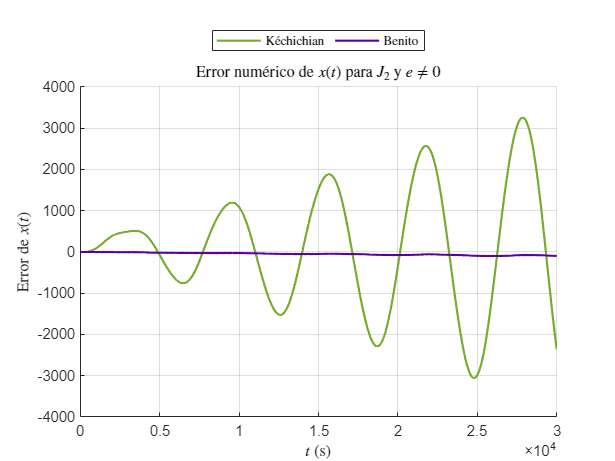

% Resolución
X0 = [x0, y0, z0, dx0, dy0, dz0];

opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-5);
[~, dXdt] = ode113(@(tOde, X) odeClohessyWiltshireECCJ2J3(tOde, X, J2, 0, R, a, e, n, INC, omega, theta_0), t, X0, opts);
    
% Comparación
plotNumericErrors(   xJ2K',    xJ2B', dXdt(:, 1), t, 'K\''echichian', 'Benito', ...
          'Error num\''erico de $x(t)$ para $J_2$ y $e \neq 0$', '$t$ (s)',       'Error de $x(t)$', '#77AC30', '#5C00A3');

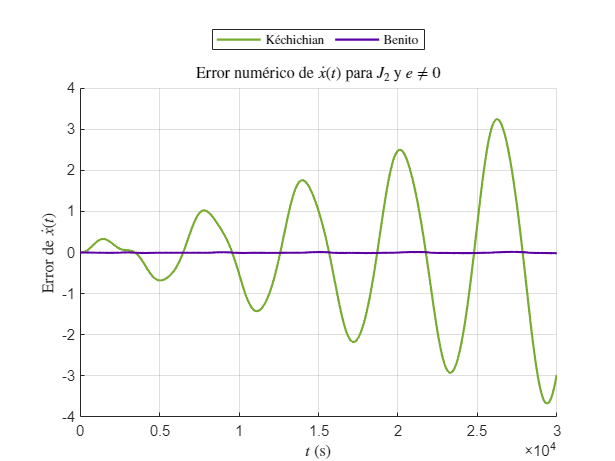

plotNumericErrors(xdotJ2K', xdotJ2B', dXdt(:, 4), t, 'K\''echichian', 'Benito', ...
    'Error num\''erico de $\dot{x}(t)$ para $J_2$ y $e \neq 0$', '$t$ (s)', 'Error de $\dot{x}(t)$', '#77AC30', '#5C00A3');

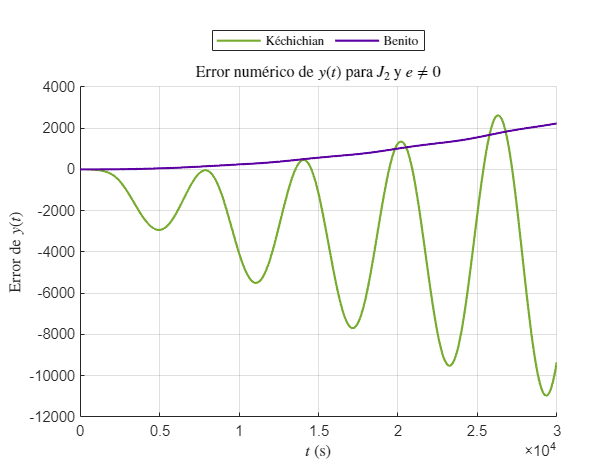

plotNumericErrors(   yJ2K',    yJ2B', dXdt(:, 2), t, 'K\''echichian', 'Benito', ...
          'Error num\''erico de $y(t)$ para $J_2$ y $e \neq 0$', '$t$ (s)',       'Error de $y(t)$', '#77AC30', '#5C00A3');

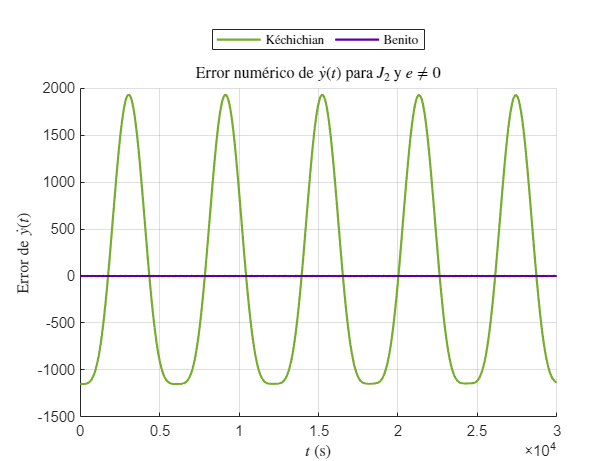

plotNumericErrors(ydotJ2K', ydotJ2B', dXdt(:, 5), t, 'K\''echichian', 'Benito', ...
    'Error num\''erico de $\dot{y}(t)$ para $J_2$ y $e \neq 0$', '$t$ (s)', 'Error de $\dot{y}(t)$', '#77AC30', '#5C00A3');

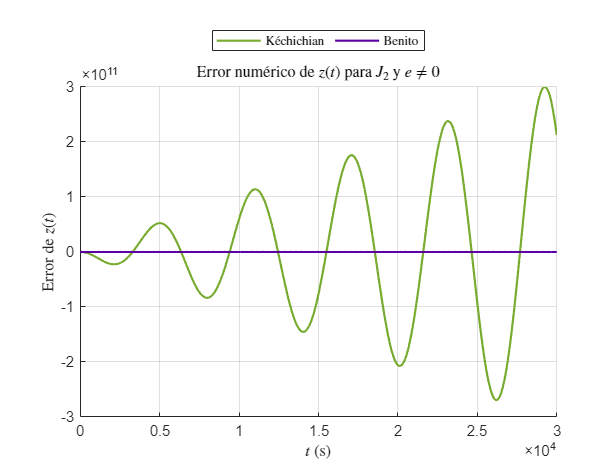

plotNumericErrors(   zJ2K',    zJ2B', dXdt(:, 3), t, 'K\''echichian', 'Benito', ...
          'Error num\''erico de $z(t)$ para $J_2$ y $e \neq 0$', '$t$ (s)',       'Error de $z(t)$', '#77AC30', '#5C00A3');

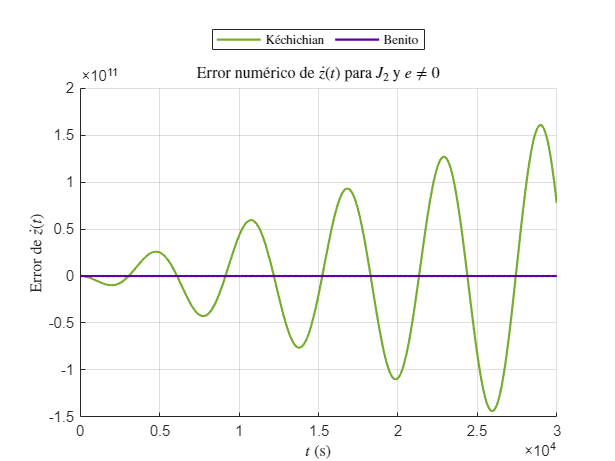

plotNumericErrors(zdotJ2K', zdotJ2B', dXdt(:, 6), t, 'K\''echichian', 'Benito', ...
    'Error num\''erico de $\dot{z}(t)$ para $J_2$ y $e \neq 0$', '$t$ (s)', 'Error de $\dot{z}(t)$', '#77AC30', '#5C00A3');

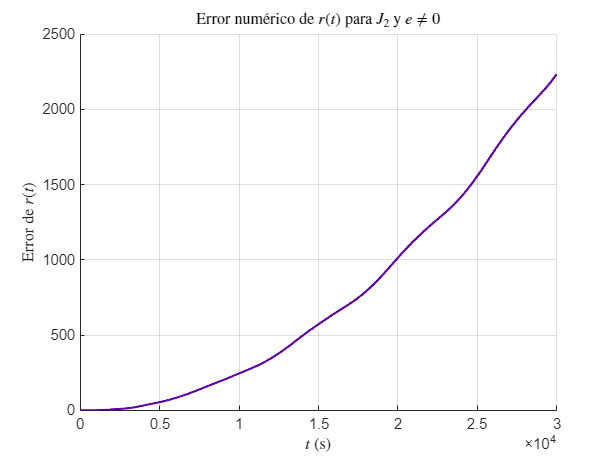


plotNumericErrorNorm([xJ2B', yJ2B', zJ2B'], dXdt(:,1:3), t, 'Error num\''erico de $r(t)$ para $J_2$ y $e \neq 0$', ...
    '$t$ (s)', 'Error de $r(t)$', '#5C00A3');

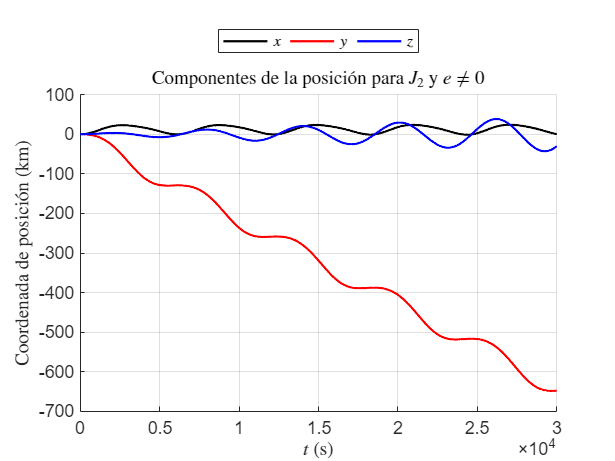



plotMultiComparisons({xJ2B / 10^3, yJ2B / 10^3, zJ2B / 10^3}, t, 'Componentes de la posici\''on para $J_2$ y $e \neq 0$', ...
    {'Coordenada de posici\''on (km)', '$t$ (s)'},  {'$x$', '$y$', '$z$'}, {'k', 'r', 'b'});

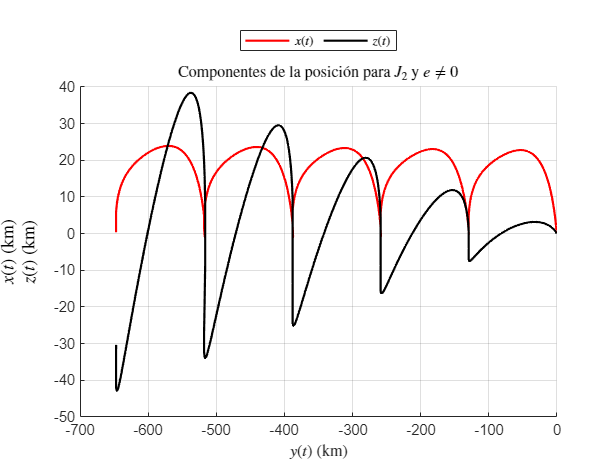

plotComparisons({yJ2B / 10^3, xJ2B / 10^3, zJ2B / 10^3}, {'$y(t)$ (km)', '$x(t)$ (km)', '$z(t)$ (km)'}, ...
   'Componentes de la posici\''on para $J_2$ y $e \neq 0$', {'$x(t)$', '$z(t)$'}, {'r', 'k'});

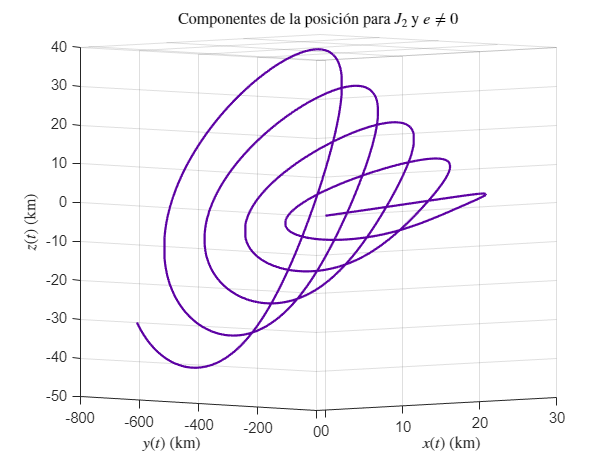

plot3D({xJ2B / 10^3, yJ2B / 10^3, zJ2B / 10^3}, [44.6 -3.1], ...
    'Componentes de la posici\''on para $J_2$ y $e \neq 0$', ...
    {'$x(t)$ (km)', '$y(t)$ (km)', '$z(t)$ (km)'}, '#5C00A3');